# Hamming(7,4)-Generator

Es wird beispielhaft der (7,4)-Hamming Code betrachtet, der aus $k=4$ Nutzbits und $m=3$ Prüfbits besteht. Zur Berechnung eines Codewortes $z$ für die Nutzdaten $x$ wird die Generatormatrix $G$ genutzt. Die Nutzdaten werden durch eine Bitvektor der Länge $k$dargestellt. 


$$z=xG$$


## Generatormatrix

n=7; k=4; m=n-k; % k Nutzbits und m Redundanzbits
P = [1 1 0; 0 1 1; 1 1 1; 1 0 1] % Berechnung der Paritätsbits

P =      1     1     0
     0     1     1
     1     1     1
     1     0     1


I_k = eye(k) % Einheitsmatrix

I_k =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


G = [I_k P] % Generatormatrix

G =      1     0     0     0     1     1     0
     0     1     0     0     0     1     1
     0     0     1     0     1     1     1
     0     0     0     1     1     0     1


## Beispiel zur Encodierung

nutzbits = [0 1 1 0] % Nutzbits

nutzbits =      0     1     1     0


codewort = mod(nutzbits*G,2)

codewort =      0     1     1     0     1     0     0


## Prüfmatrix (Parity-Check Matrix)

Zur Überprüfung eines empfangenen Codewortes wird die Prüfmatrix $H$gebildet, aus der dann das Fehlersyndrom berechnet wird.

H = [P' eye(n-k) ]

H =      1     0     1     1     1     0     0
     1     1     1     0     0     1     0
     0     1     1     1     0     0     1


## Fehlersyndrom bei fehlerfreier Übertragung

syndrom=mod(codewort*H',2)

syndrom =      0     0     0


## Fehlersyndrom bei fehlerhafter Übertragung.

Das Fehlersyndrom zeigt an, welches Bit fehlerhaft ist. Ein Fehler in Bit $i$ führt zu einem Fehlersyndrom, welches identisch zur $i$.ten Spalte der Prüfmatrix $H$ist.

i=7; % Bit i ist fehlerhaft.
codewortMitFehler=codewort;codewortMitFehler(i)=1-codewort(i)

codewortMitFehler =      0     1     1     0     1     0     1


syndromBeiFehler=mod(codewortMitFehler*H',2)

syndromBeiFehler =      0     0     1



spalteInH = find(ismember(H',syndromBeiFehler,'rows'),1)

spalteInH = 7

fprintf('Simulierter Fehler in Bit i = %d\n',i);

Simulierter Fehler in Bit i = 7


fprintf('Syndrom identisch zu Spalte %d in H -> Bitfehler an Position %d.\n',spalteInH,spalteInH);

Syndrom identisch zu Spalte 7 in H -> Bitfehler an Position 7
.

# Hamming-Distanz empirisch ermitteln

Die Distanz zwischen allen Codewörtern des (7,4) Hamming Codes wird empirisch bestimmt. Daraus wird die minimale Hamming-Distanz ermittelt, aus der sich die Anzahl der erkennbaren und korrigierbaren Fehler ergibt.

## Alle Codewörter erzeugen

D = [0:2^k - 1];
B = dec2bin(D);
codewort = mod(B*G,2);

## Grafische Darstellung aller Codewörter

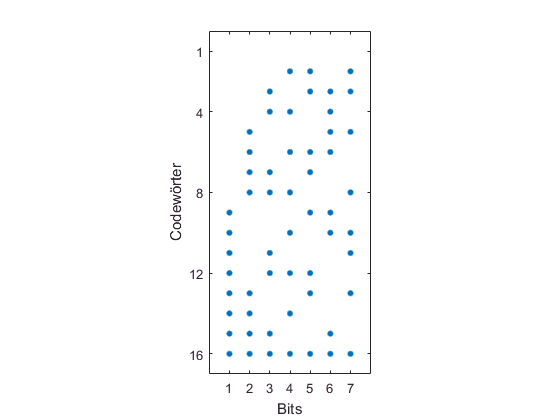

figure(1);clf;
spy(codewort)
set(gca,'ytick',[1 4 8 12 16],'xtick',1:7);
xlabel('Bits')
ylabel('Codewörter')

## Distanz zu allen anderen Codewörtern

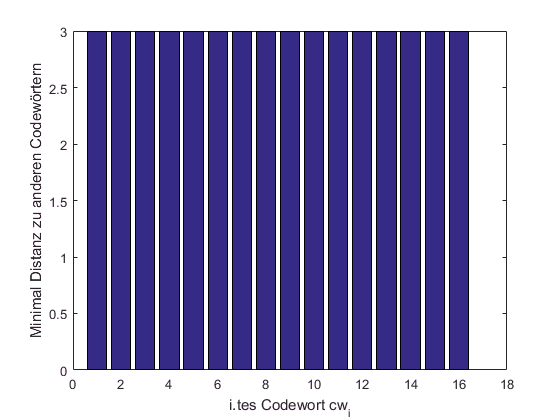

allDist=zeros(2^k,1); % allDist(:,i) : distances of codewort cw_i to other 
minDist=zeros(2^k,1);
goto=zeros(2^k,1);
for i=1:2^k
    deltas=sum(abs(repmat(codewort(i,:),2^k,1)-codewort),2);
    allDist(:,i)=deltas;
    [minDist(i),ind]=min(deltas(setdiff(1:2^k,i)));
    goto(i)=ind;
end
figure(2);clf;bar(minDist);xlabel('i.tes Codewort cw_i');ylabel('Minimal Distanz zu anderen Codewörtern')

# Restfehlerwahrscheinlichkeit des Hamming-Codes

Die Restfehlerwahrscheinlichkeit gibt die Wahrscheinlichkeit an, dass ein verfälschtes Codewort nicht korrigiert werden kann und sich dieses außerhalb der Korrigierkugel befindet. Die Hamming-Distanz ist $h=3$. Die Restfehlerwahrscheinlichkeit ist dann bei einer Bitfehlerwahrscheinlichkeit $p_b$ und Codewortlänge $n=k+m$ wie folgt.


$$t=\lfloor\frac{h-1}{2}\rfloor \\
P(F>t)=1-\sum_{i=0}^t \pmatrix{n \cr i} p_b^i(1-p_b)^{n-i}$$


figure(3);clf;
p_b=linspace(0,0.1,101); % Bit Error Rate
t=floor((3-1)/2) % Ein Fehler kann korrigiert werden

t = 1

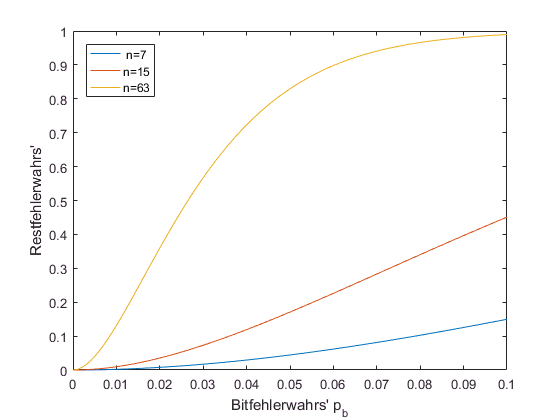

myn=[7 15 63];
for n=myn
    plot(p_b,1-binocdf(t,n,p_b),'-');
    hold all;
end
xlabel('Bitfehlerwahrs'' p_b');
ylabel('Restfehlerwahrs''');
legend(num2str(myn','n=%d'),'location','northwest');

# Parameterkombinationen bei Hamming-Codes

Wir betrachten einen Hamming-Code mit $m$ Kontrollbits und $k$Nutzbits. Die Hamming-Schranke gibt dabei die maximale Länge der Nutzbits in Abhängigkeit der Kontrollbits vor.


$$k\leq 2^m-m-1$$


Bei einem perfekten Code wird die maximale Länge der Nutzbits erreicht.

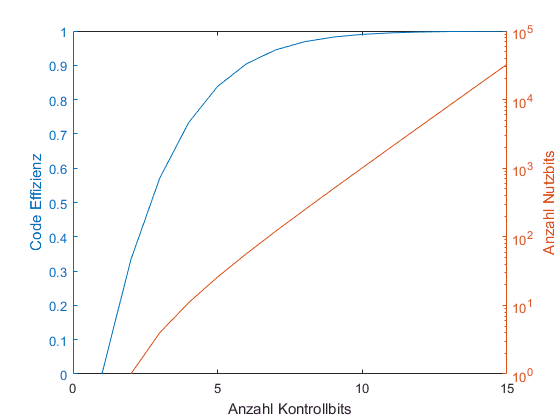

figure(4);clf;
m=1:15; % Kontrollbits
k=2.^m-m-1; % Nutzbits
yyaxis left
plot(m,k./(k+m))
ylabel('Code Effizienz')
yyaxis right
semilogy(m,k)
xlabel('Anzahl Kontrollbits')
ylabel('Anzahl Nutzbits')

## Trade-off zwischen Code Effizienz und Restfehlerwahrscheinlichkeit

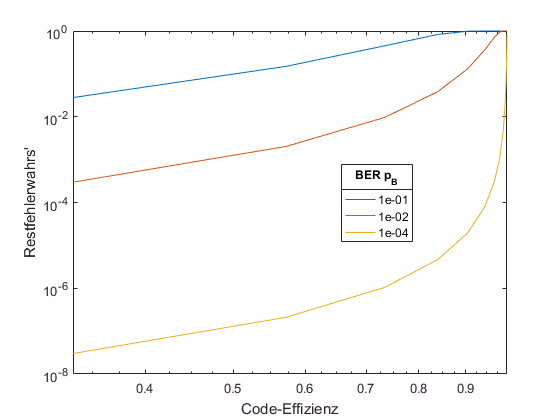

figure(5);clf;
mypb=[1e-1 1e-2 1e-4];
for pb=mypb
    loglog(k./(k+m),1-binocdf(t,k+m,pb))
    hold all
end
ylabel('Restfehlerwahrs''')
xlabel('Code-Effizienz')
h=legend(num2str(mypb','%.0e'),'location','best');
title(h,'BER p_B');